clc;
close all;
clear;
load("robot.mat");

Initial: 240,0,230

Intermediate: 100,-100,265

Final: 160,160,100

d1 = 0.127;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;
dhparams = [0,   	   0,    	d1,      0;
            a1,       -pi/2,    0,       0;
            a2,        0,    	0,       0;
            a3,       -pi/2,    d4,      0;
            0,         pi/2,    0,       0;
            0,         pi/2,    d6,      0];

ee_guessinit = [0,0,0,0,0,0];
ee_init = [0,23.1,-25.7,0,2.6,0];
ee_init = ee_init*pi/180;
ee_inter = [-44.9,-25.1,9.7,0,15.4,44.9];
ee_inter = ee_inter*pi/180;
ee_final = [44.9,31.0,9.8,0,-40.8,-44.9];
ee_final = ee_final*pi/180;

#### angle transform

homeconfig = homeConfiguration(robot);
initconfig = homeconfig + ee_init';
interconfig = homeconfig + ee_inter';
finalconfig = homeconfig + ee_final';
% Initial = homeconfig + ee_init';
% Intermediate = homeconfig + ee_inter';
% Final = homeconfig + ee_final';

%% Iterative Inverse Kinematics
syms th1 th2 th3 th4 th5 th6

T01 = dh_transmatrix(0,0,d1,th1);
T12 = dh_transmatrix(a1,-pi/2,0,th2);
T23 = dh_transmatrix(a2,0,0,th3);
T34 = dh_transmatrix(a3,-pi/2,d4,th4);
T45 = dh_transmatrix(0,pi/2,0,th5);
T56 = dh_transmatrix(0,pi/2,d6,th6);

T06 = T01 * T12 * T23 * T34 * T45 * T56;
T = simplify(T06);

Q_t = T(1:3,4);                               % Translation Vector
JQ = jacobian(Q_t,[th1,th2,th3,th4,th5,th6]);             % Jacobian Matrix 

P1 = subs(Q_t,th1,interconfig(1));            % Substitute each angle from symbol to number in initial condition. 
P2 = subs(P1,th2,interconfig(2));
P3 = subs(P2,th3,interconfig(3));
P4 = subs(P3,th4,interconfig(4));
P5 = subs(P4,th5,interconfig(5));
P6 = subs(P5,th6,interconfig(6));
p_target_inter = double(P6);                       % Calculating the final position from given final angle, convert from symbolic type to double type.

P1 = subs(Q_t,th1,finalconfig(1));
P2 = subs(P1,th2,finalconfig(2));
P3 = subs(P2,th3,finalconfig(3));
P4 = subs(P3,th4,finalconfig(4));
P5 = subs(P4,th5,finalconfig(5));
P6 = subs(P5,th6,finalconfig(6));
p_target_final = double(P6);  

theta_k_1 = initconfig;                   % Initial interative, note that since you have four rows, the homeconfig is a 4 by 1 vector, we only need first 3 elements            

%% Newton Raphson's loop
constraint_theta = [-100, 160; %Angle constraints
                    -40-90, 70-90;
                    -170, 60;
                    -350, 350; 
                    -205+90, 36+90;
                    -360, 360];
constraint_theta = constraint_theta/180*pi;

Q1 = subs(Q_t,th1,theta_k_1(1));
Q2 = subs(Q1,th2,theta_k_1(2));
Q3 = subs(Q2,th3,theta_k_1(3));
Q4 = subs(Q3,th4,theta_k_1(4));
Q5 = subs(Q4,th5,theta_k_1(5));
Q6 = subs(Q5,th6,theta_k_1(6));
Q_k_1 = double(vpa(Q6,12)); % Translation vector for theta_k_1, Convert from symbolic to numeric 

p_number = 30; %split the path
delta_x = (norm(p_target_inter)- norm(Q_k_1))/p_number;
p_number_2 = round((norm(p_target_final)- norm(p_target_inter))/delta_x)

p_number_2 = 50

target_points_init_to_inter = split_target_points(Q_k_1,p_target_inter,p_number);
target_points_inter_to_final = split_target_points(p_target_inter,p_target_final,p_number_2);
target_points_inter_to_final(:,1) = [];
target_points = cat(2,target_points_init_to_inter,target_points_inter_to_final);

theta_list = theta_k_1;   
ee_positions = Q_k_1;
target_point_pre = target_points(:,1);
for j = 2:length(target_points)
    [theta_result,Q_k_1] = interative_ik(theta_list(:,j-1),target_points(:,j),T); % calculate ik joint angle 
    theta_list = [theta_list,theta_result];
    ee_positions = [ee_positions,Q_k_1];
end

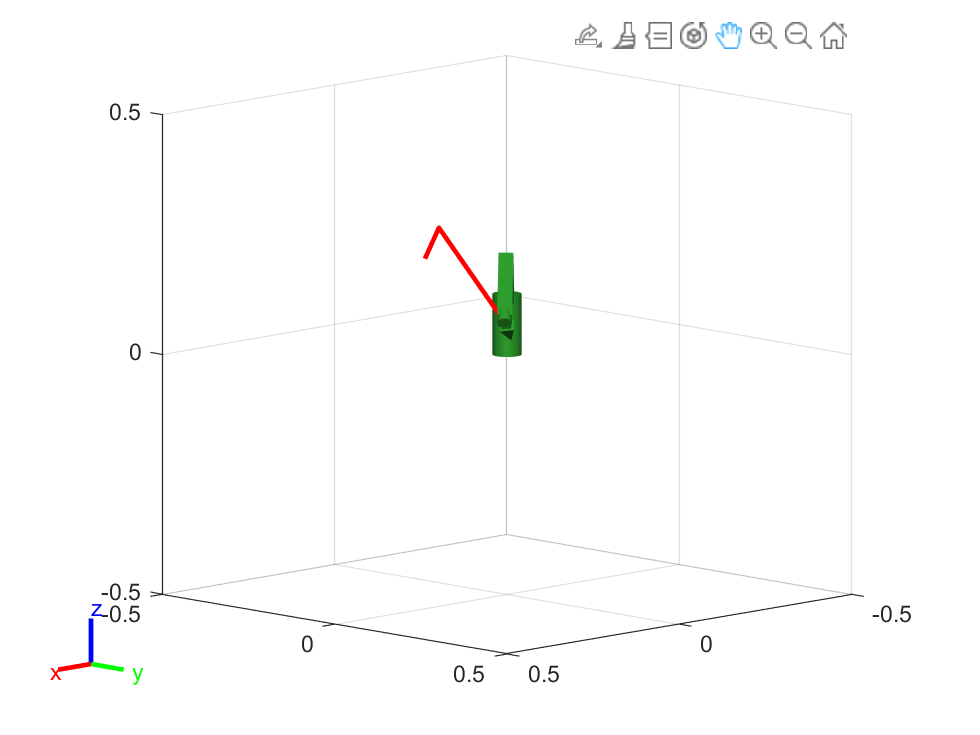

Step = 1;
num_joints = length(homeconfig);
framesPerSecond = 30;

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, theta_list(:,1), 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2);

v = VideoWriter('Task3.avi');
v.FrameRate = 15;
open(v);
for j = 2 : length(theta_list)
    Qd = theta_list(:,j);
    show(robot, Qd, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
    set(trajectoryPlot, 'XData', ee_positions(1, 1:j), 'YData', ee_positions(2, 1:j), 'ZData', ee_positions(3, 1:j));
    drawnow;
    frame = getframe(gcf);
    writeVideo(v, frame);
end
hold(ax, 'off');

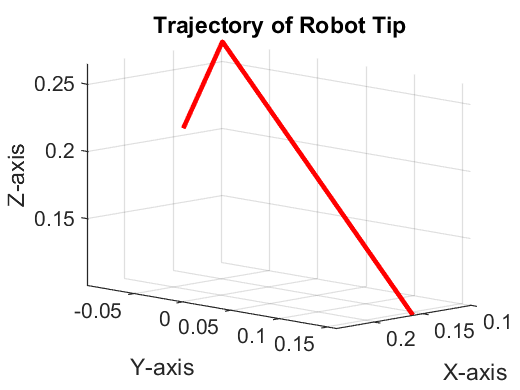

close(v);
figure('Color', [1 1 1]);
plot3(ee_positions(1, :),ee_positions(2, :),ee_positions(3, :), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory of Robot Tip');
axis equal;
view(135, 10); 

% figure
% plot3(ee_positions(1, :),ee_positions(2, :),ee_positions(3, :),'r', 'LineWidth', 1);
% xlabel('X-axis');
% ylabel('Y-axis');
% zlabel('Z-axis');
% title('Trajectory Plot');
% grid on;


figure;
grid on;
grid minor;
hold on;
dt = 0.01;
joint_positions = theta_list

joint_positions =          0   -0.0139   -0.0284   -0.0435   -0.0592   -0.0755   -0.0924   -0.1101   -0.1285   -0.1477   -0.1676   -0.1884   -0.2100   -0.2326   -0.2560   -0.2804   -0.3058   -0.3322   -0.3596   -0.3881   -0.4176   -0.4482   -0.4798   -0.5125   -0.5462   -0.5808   -0.6164   -0.6529   -0.6902   -0.7283   -0.7670   -0.7349   -0.7016   -0.6671   -0.6315   -0.5947   -0.5568   -0.5178   -0.4779   -0.4372   -0.3957   -0.3537   -0.3111   -0.2683   -0.2253   -0.1823   -0.1395   -0.0970   -0.0550   -0.0136
   -1.1676   -1.2081   -1.2479   -1.2869   -1.3253   -1.3630   -1.4001   -1.4364   -1.4721   -1.5072   -1.5415   -1.5750   -1.6078   -1.6397   -1.6708   -1.7009   -1.7300   -1.7580   -1.7848   -1.8105   -1.8348   -1.8577   -1.8791   -1.8990   -1.9172   -1.9338   -1.9485   -1.9614   -1.9724   -1.9815   -1.9885   -2.0180   -2.0462   -2.0730   -2.0983   -2.1220   -2.1440   -2.1642   -2.1823   -2.1982   -2.2118   -2.2229   -2.2312   -2.2367   -2.2392   -2.2384   -2.2344   -2.2269 

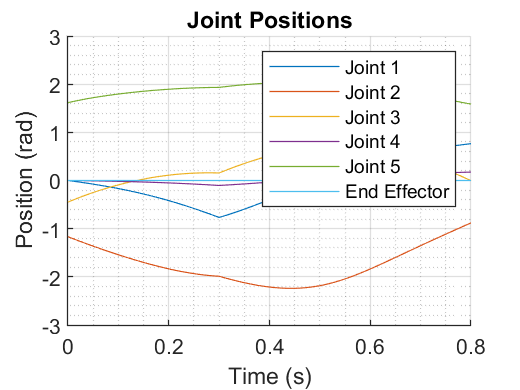

plot(0:dt:(length(joint_positions)-1)*dt, joint_positions);
title("Joint Positions");
xlabel("Time (s)");
ylabel("Position (rad)");
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'End Effector');
hold off;

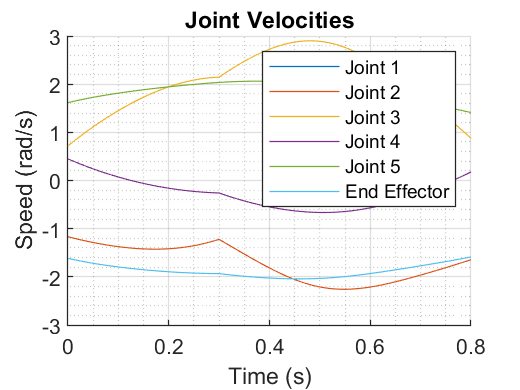


% Calculate speed
speedMatrix = diff(theta_list) ./ diff((1:size(theta_list, 1))');
speedMatrix = [NaN(1, size(theta_list, 2)); speedMatrix];

figure;
grid on;
grid minor;
hold on;
plot(0:dt:(length(joint_positions)-1)*dt,speedMatrix);
title("Joint Velocities");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'End Effector');
hold off;

%joint_positions = theta_list
% figure;
% grid on;
% grid minor;
% hold on;
% for i = 1:6
%     %subplot(6, 1, i);
%     plot(joint_positions(i,:),'LineWidth',1);
% end
% title("Joint Positions");
% legend('joint 1','joint 2','joint 3','joint 4','joint 5','joint 5');
% hold off;
% dt = 1;
% joint_velocities = diff(theta_list)/dt;
% joint_velocities = [joint_velocities; zeros(1,length(joint_velocities))];
% figure;
% grid on;
% grid minor;
% hold on;
% for i = 1:6
%     %subplot(6, 1, i);
%     plot(joint_velocities(i,:),'LineWidth',1);
% end
% title("Joint Velocities");
% legend('joint 1','joint 2','joint 3','joint 4','joint 5','joint 5');
% hold off;

Task3_theta_list = theta_list;
Task3_theta_list(2,:) = Task3_theta_list(2,:) + pi/2;
Task3_theta_list(5,:) = Task3_theta_list(5,:) - pi/2;
save("Task3_theta_list.mat","Task3_theta_list");

function to split the path

function target_points = split_target_points(p_init,p_target,p_number)
target_points = zeros(3,p_number+1);
Vp_to_target = p_target-p_init; % total vector from guessed position to desired target position 
delta_p = Vp_to_target/p_number;
target_points(:,1) = p_init;
for i = 2:p_number+1
    target_points(:,i) = target_points(:,i-1)+delta_p;
end
end

function to calculate transform matrix according to one line of the MDH table

function T = dh_transmatrix(a,alpha,d,theta)
    T = [   cos(theta),             -sin(theta),            0,           a;
            sin(theta)*cos(alpha),  cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
            sin(theta)*sin(alpha),  cos(theta)*sin(alpha),  cos(alpha),  cos(alpha)*d;
            0,                      0,                      0,           1];
end